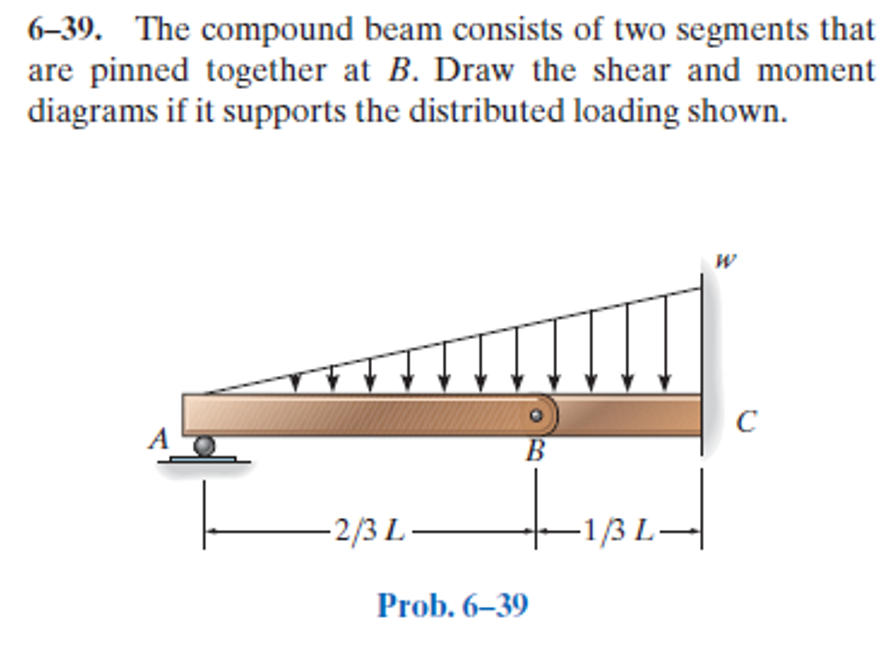

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-39P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-39P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo');
L = sym('L', 'positive');
w1 = findpoly(1, 'thru', [0 0], 'thru', [L -wo]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('hinge', 'force', 'Hb', 2*L/3);
b = b.add('reaction', 'force', 'Rc', L);
b = b.add('reaction', 'moment', 'Mc', L);
b = b.add('distributed', 'force', w1, [0 L]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,\left(27\,L^{4}-40\,L^{2}\,x^{2}+27\,x^{4}\right)}{3240\,\text{E}\,\text{I}\,L} & \text{ if }3\,x\leq 2\,L\\ -\frac{\mathrm{wo}\,{\left(L-x\right)}^{2}\,\left(28\,L^{3}+41\,L^{2}\,x+54\,L\,x^{2}+27\,x^{3}\right)}{3240\,\text{E}\,\text{I}\,L} & \text{ if }2\,L<3\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(9\,L^{4}-40\,L^{2}\,x^{2}+45\,x^{4}\right)}{1080\,\text{E}\,\text{I}\,L} & \text{ if }3\,x\leq 2\,L\\ \frac{\mathrm{wo}\,\left(L+x\right)\,\left(L^{2}+9\,x^{2}\right)\,\left(L-x\right)}{216\,\text{E}\,\text{I}\,L} & \text{ if }2\,L<3\,x \end{array}\right.$$

m

$$m(x) = \frac{\mathrm{wo}\,x\,\left(2\,L-3\,x\right)\,\left(2\,L+3\,x\right)}{54\,L}$$

v

$$v(x) = \frac{\mathrm{wo}\,\left(4\,L^{2}-27\,x^{2}\right)}{54\,L}$$

w

$$w(x) = -\frac{\mathrm{wo}\,x}{L}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Mc} & -\frac{5\,L^{2}\,\mathrm{wo}}{54}\\ \mathrm{Ra} & \frac{2\,L\,\mathrm{wo}}{27}\\ \mathrm{Rc} & \frac{23\,L\,\mathrm{wo}}{54} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & \frac{4\,L\,\mathrm{wo}}{27} \end{array}\right)$$

# shear and moment diagram

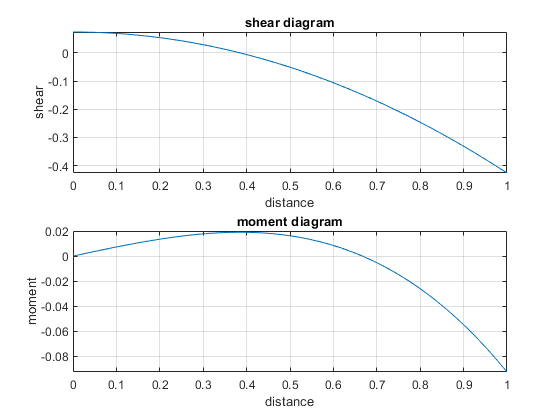

beam.shear_moment(m, v, [0 1], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;